data_path = "C:\Users\wynga\OneDrive\Desktop\PhD_Research\Gambling\NFL 2023 to 2024 Season Money Lines.xlsx";

warning off
for week_number = 5:18
    % Action Network Data only Available after Week 4
    data_table = readtable(data_path,'Sheet',sprintf('Week %d',week_number));
    num_games = length(data_table.Teams)/2;
    for game_number = 1:num_games
        game_data(week_number,game_number).home_team = data_table.Teams{2*game_number};
        game_data(week_number,game_number).home_outcome = data_table.Outcome{2*game_number};
        game_data(week_number,game_number).home_opening_odds = data_table.OpeningMoneyline(2*game_number);
        game_data(week_number,game_number).home_best_odds = data_table.BestOdds(2*game_number);
        game_data(week_number,game_number).home_power_ranking = data_table.PowerRanking(2*game_number);
        game_data(week_number,game_number).home_bet_percent = data_table.x_OfBets(2*game_number);
        game_data(week_number,game_number).home_money_percent = data_table.x_OfMoney(2*game_number);

        game_data(week_number,game_number).away_team = data_table.Teams{2*game_number-1};
        game_data(week_number,game_number).away_outcome = data_table.Outcome{2*game_number-1};
        game_data(week_number,game_number).away_opening_odds = data_table.OpeningMoneyline(2*game_number-1);
        game_data(week_number,game_number).away_best_odds = data_table.BestOdds(2*game_number-1);
        game_data(week_number,game_number).away_power_ranking = data_table.PowerRanking(2*game_number-1);
        game_data(week_number,game_number).away_bet_percent = data_table.x_OfBets(2*game_number-1);
        game_data(week_number,game_number).away_money_percent = data_table.x_OfMoney(2*game_number-1);
    end

    for game_number = num_games+1:16
        % For Teams on a Bye Week
        game_data(week_number,game_number).home_team = 'NA';
        game_data(week_number,game_number).home_outcome = 'NA';
        game_data(week_number,game_number).home_opening_odds = nan;
        game_data(week_number,game_number).home_best_odds = nan;
        game_data(week_number,game_number).home_power_ranking = nan;
        game_data(week_number,game_number).home_bet_percent = nan;
        game_data(week_number,game_number).home_money_percent= nan;

        game_data(week_number,game_number).away_team = 'NA';
        game_data(week_number,game_number).away_outcome = 'NA';
        game_data(week_number,game_number).away_opening_odds = nan;
        game_data(week_number,game_number).away_best_odds = nan;
        game_data(week_number,game_number).away_power_ranking = nan;
        game_data(week_number,game_number).away_bet_percent = nan;
        game_data(week_number,game_number).away_money_percent = nan;
    end

end

for week_number = 1:4
    % For Weeks without Action Network Data
    for game_number = 1:16

        game_data(week_number,game_number).home_team = 'NA';
        game_data(week_number,game_number).home_outcome = 'NA';
        game_data(week_number,game_number).home_opening_odds = nan;
        game_data(week_number,game_number).home_best_odds = nan;
        game_data(week_number,game_number).home_power_ranking = nan;
        game_data(week_number,game_number).home_bet_percent = nan;
        game_data(week_number,game_number).home_money_percent= nan;

        game_data(week_number,game_number).away_team = 'NA';
        game_data(week_number,game_number).away_outcome = 'NA';
        game_data(week_number,game_number).away_opening_odds = nan;
        game_data(week_number,game_number).away_best_odds = nan;
        game_data(week_number,game_number).away_power_ranking = nan;
        game_data(week_number,game_number).away_bet_percent = nan;
        game_data(week_number,game_number).away_money_percent = nan;
    end
end

warning on

team_names = sort(horzcat({game_data(18,:).home_team},{game_data(18,:).away_team}));
% 'ARI' 'ATL' 'BAL' 'BUF' 'CAR' 'CHI' CIN' 'CLE' 'DAL' 'DEN' 'DET' 'GB'
% 'HOU' 'IND' 'JAX' 'KC' 'LAC' 'LAR' 'LV' 'MIA' 'MIN' 'NE' 'NO' 'NYG'
% 'NYJ' 'PHI' 'PIT' 'SEA' 'SF' 'TB' 'TEN' WAS'


## Team Records Check


team_wins =  [1 2 3 3 0 0 1 2 3 1 3 2 ...
    2 2 2 3 2 2 1 3 1 1 2 1 ...
    1 4 2 3 4 3 2 2];
team_losses = [3 2 1 1 4 4 3 2 1 3 1 2 ...
    2 2 2 1 2 2 3 1 3 3 2 3 ...
    3 0 2 1 0 1 2 2];
team_ties = 4-team_wins-team_losses;


for week_number = 5:18
    home_teams = string({game_data(week_number,:).home_team});
    away_teams = string({game_data(week_number,:).away_team});
    home_outcomes = {game_data(week_number,:).home_outcome};
    away_outcomes = {game_data(week_number,:).away_outcome};
    for team_number = 1:32
        if ismember(string(team_names{team_number}),home_teams)
            team_outcome = home_outcomes(ismember(home_teams,string(team_names{team_number})));
        elseif ismember(string(team_names{team_number}),away_teams)
            team_outcome = away_outcomes(ismember(away_teams,string(team_names{team_number})));
        else
            team_outcome = 'NA';
        end

        if strcmpi(team_outcome,'W')
            team_wins(team_number) = team_wins(team_number) + 1;
        elseif strcmpi(team_outcome,'L')
            team_losses(team_number) = team_losses(team_number) + 1;
        elseif strcmpi(team_outcome,'T')
            team_ties(team_number) = team_ties(team_number) + 1;
        end
    end
end

team_records = cell(4,32);
[~,rankings] = sort(team_wins,'descend');
for team_number = 1:32
    team_records{1,team_number} = team_names{rankings(team_number)};
    team_records{2,team_number} = team_wins(rankings(team_number));
    team_records{3,team_number} = team_losses(rankings(team_number));
    team_records{4,team_number} = team_ties(rankings(team_number));
end


## Power Rankings Check

for week_number = 5:18
    team_names = horzcat({game_data(week_number,:).home_team},{game_data(week_number,:).away_team});
    team_power_rankings = horzcat([game_data(week_number,:).home_power_ranking],[game_data(week_number,:).away_power_ranking]);

    [team_power_rankings,sorted_indeces] = sort(team_power_rankings);
    team_names = team_names(sorted_indeces);

    %     fprintf('Week %d:',week_number)
    for team_number = 1:length(team_names)
        if ~isnan(team_power_rankings(team_number))
            %             fprintf('%d %s\n',team_power_rankings(team_number),string(team_names(team_number)));
        end
    end
end



## Moneyline Check

moneyline_errors = 0;

for week_number = 5:18
    for game_number = 1:16
        home_opening_odds = game_data(week_number,game_number).home_opening_odds;
        home_best_odds = game_data(week_number,game_number).home_best_odds;
        away_opening_odds = game_data(week_number,game_number).away_opening_odds;
        away_best_odds = game_data(week_number,game_number).away_best_odds;

        if  (~isnan(home_opening_odds) && isnan(home_best_odds))
            fprintf('Week %d %s has incomplete moneyline data\n',week_number,string(game_data(week_number,game_number).home_team))
            fprintf('    Assume Best Odds equals Opening Odds\n')
            game_data(week_number,game_number).home_best_odds = game_data(week_number,game_number).home_opening_odds;
            moneyline_errors = moneyline_errors + 1;

        elseif (isnan(home_opening_odds) && ~isnan(home_best_odds))
            fprintf('Week %d %s has incomplete moneyline data\n',week_number,string(game_data(week_number,game_number).home_team))
            fprintf('    Assume Opening Odds equals Best Odds')
            game_data(week_number,game_number).home_opening_odds = game_data(week_number,game_number).home_best_odds;
            moneyline_errors = moneyline_errors + 1;

        elseif home_opening_odds > home_best_odds
            fprintf('Week %d %s has a ''best'' moneyline worse than opening\n',week_number,string(game_data(week_number,game_number).home_team))
            fprintf('    Assume Best Odds equals Opening Odds\n')
            game_data(week_number,game_number).home_best_odds = game_data(week_number,game_number).home_opening_odds;
            moneyline_errors = moneyline_errors + 1;

        end

        if  (~isnan(away_opening_odds) && isnan(away_best_odds))
            fprintf('Week %d %s has incomplete moneyline data\n',week_number,string(game_data(week_number,game_number).away_team))
            fprintf('    Assume Best Odds equals Opening Odds\n')
            game_data(week_number,game_number).away_best_odds = game_data(week_number,game_number).away_opening_odds;
            moneyline_errors = moneyline_errors + 1;

        elseif (isnan(away_opening_odds) && ~isnan(away_best_odds))
            fprintf('Week %d %s has incomplete moneyline data\n',week_number,string(game_data(week_number,game_number).away_team))
            fprintf('    Assume Opening Odds equals Best Odds\n')
            game_data(week_number,game_number).away_opening_odds = game_data(week_number,game_number).away_best_odds;
            moneyline_errors = moneyline_errors + 1;

        elseif away_opening_odds > away_best_odds
            fprintf('Week %d %s has a ''best'' moneyline worse than opening\n',week_number,string(game_data(week_number,game_number).away_team))
            fprintf('    Assume Best Odds equals Opening Odds\n')
            game_data(week_number,game_number).away_best_odds = game_data(week_number,game_number).away_opening_odds;
            moneyline_errors = moneyline_errors + 1;

        end


    end
end

Week 6 ATL has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 6 JAX has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 6 PHI has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 7 DEN has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 7 PHI has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 7 NO has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 8 JAX has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 8 WAS has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 9 SEA has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 9 PIT has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 9 NYJ has incomplete moneyline data


    Assume Opening Odds equals Best Odds

Week 9 LAC has incomplete moneyline data


    Assume Opening Odds equals Best Odds


Week 10 NE has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 11 NYG has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 11 SF has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 11 BAL has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 12 LAR has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 12 DEN has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 12 LV has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 12 HOU has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 12 BUF has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 12 MIN has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 13 NYJ has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 13 NE has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 13 CLE has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 13 ARI has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 13 SF has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 14 CAR has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 14 NYJ has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 14 CIN has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 14 NE has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 15 GB has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 15 HOU has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 15 NYJ has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 15 BUF has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 15 PHI has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 16 TEN has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 16 CLE has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 16 JAX has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 16 MIN has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 17 CAR has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 17 LV has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 17 HOU has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 17 TB has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 18 SF has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 18 LV has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds


Week 18 DET has a 'best' moneyline worse than opening


    Assume Best Odds equals Opening Odds



fprintf('\nThere were %d moneyline errors\n',moneyline_errors)


There were 47 moneyline errors


## 'Smart Money' Analysis

smart_picks_index = 1;

for week_number = 1:18
    for game_number = 1:16

        home_money_percent = game_data(week_number,game_number).home_money_percent;
        home_bet_percent = game_data(week_number,game_number).home_bet_percent;
        away_money_percent = game_data(week_number,game_number).away_money_percent;
        away_bet_percent = game_data(week_number,game_number).away_bet_percent;
        home_outcome = game_data(week_number,game_number).home_outcome;
        away_outcome = game_data(week_number,game_number).away_outcome;
        home_team = game_data(week_number,game_number).home_team;
        away_team = game_data(week_number,game_number).away_team;

        % For the MoneyLine, I will be using the Opening Odds
        home_odds = game_data(week_number,game_number).home_opening_odds;
        away_odds = game_data(week_number,game_number).away_opening_odds;

        bet_percents_exist = ~isnan(home_bet_percent) && ~isnan(away_bet_percent);
        money_percents_exist = ~isnan(home_money_percent) && ~isnan(away_money_percent);
        money_line_exists = ~isnan(home_odds) && ~isnan(away_odds);

        if bet_percents_exist && money_percents_exist && (home_money_percent ~= home_bet_percent) && money_line_exists

            smart_picks(smart_picks_index).home_bet_percent = home_bet_percent;
            smart_picks(smart_picks_index).away_bet_percent = away_bet_percent;
            smart_picks(smart_picks_index).home_money_percent = home_money_percent;
            smart_picks(smart_picks_index).away_money_percent = away_money_percent;
            smart_picks(smart_picks_index).home_outcome = home_outcome;
            smart_picks(smart_picks_index).away_outcome = away_outcome;
            smart_picks(smart_picks_index).home_odds = home_odds;
            smart_picks(smart_picks_index).away_odds = away_odds;
            smart_picks(smart_picks_index).home_team = home_team;
            smart_picks(smart_picks_index).away_team = away_team;
            smart_picks(smart_picks_index).week_number = week_number;

            if home_money_percent/home_bet_percent > away_money_percent/away_bet_percent
                smart_picks(smart_picks_index).smart_choice = "home";

            elseif home_money_percent/home_bet_percent < away_money_percent/away_bet_percent
                smart_picks(smart_picks_index).smart_choice = "away";

            end
            smart_picks_index = smart_picks_index + 1;

        end
    end
end

smart_picks

smart_picks = 1×193 struct array with fields:
    home_bet_percent
    away_bet_percent
    home_money_percent
    away_money_percent
    home_outcome
    away_outcome
    home_odds
    away_odds
    smart_choice
    home_team
    away_team
    week_number


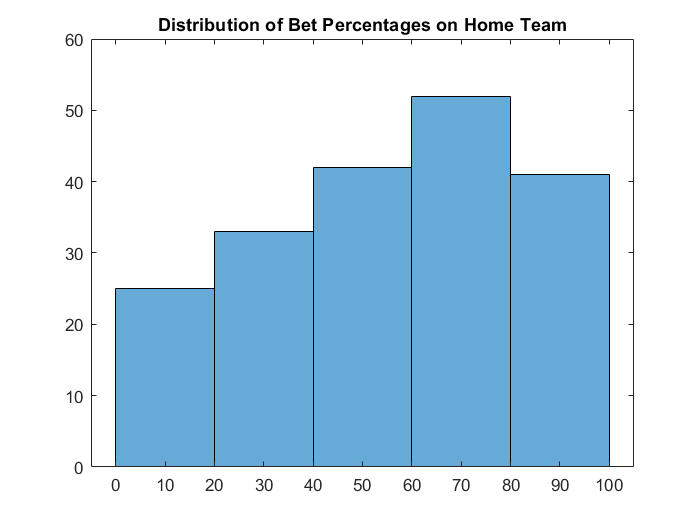

histogram([smart_picks(:).home_bet_percent])
title('Distribution of Bet Percentages on Home Team')

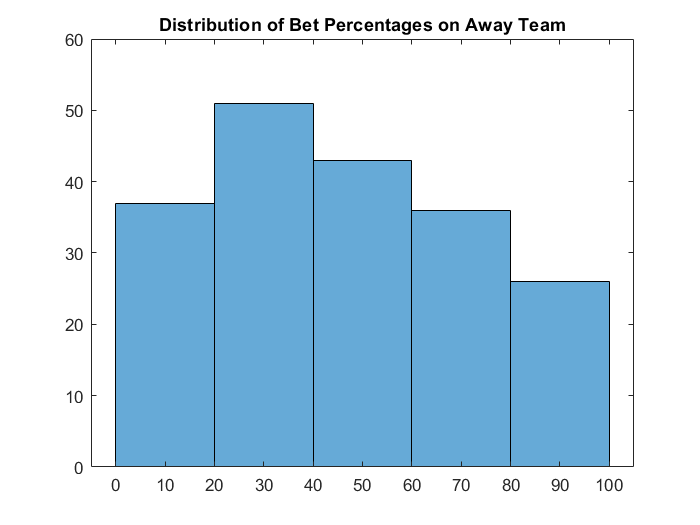

histogram([smart_picks(:).away_bet_percent])
title('Distribution of Bet Percentages on Away Team')

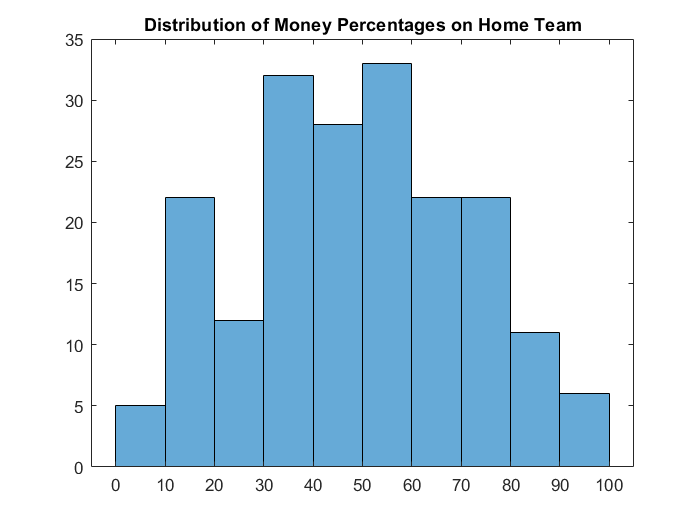

histogram([smart_picks(:).home_money_percent])
title('Distribution of Money Percentages on Home Team')

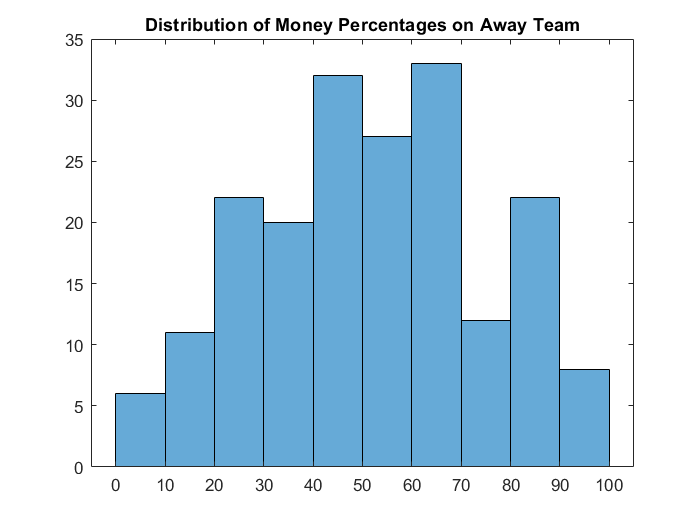

histogram([smart_picks(:).away_money_percent])
title('Distribution of Money Percentages on Away Team')

histogram([])

% Notice how the Bet Percentages favor the Home Team but the Money
% Percentages are (roughly, very roughly) normal about p = 1/2

%% FIRST RUN: ASSUME BET ON ALL 'SMART MONEY' BETS IS $100
betting_gains = 0;
for smart_picks_index = 1:length(smart_picks)
    if strcmpi(smart_picks(smart_picks_index).smart_choice,"home") && strcmpi(smart_picks(smart_picks_index).home_outcome,'W')
        if smart_picks(smart_picks_index).home_odds < 0
            betting_gains = betting_gains - 10000/smart_picks(smart_picks_index).home_odds;
        else
            betting_gains = betting_gains + smart_picks(smart_picks_index).home_odds;
        end
    elseif strcmpi(smart_picks(smart_picks_index).smart_choice,"away") && strcmpi(smart_picks(smart_picks_index).away_outcome,'W')
        if smart_picks(smart_picks_index).away_odds < 0
            betting_gains = betting_gains - 10000/smart_picks(smart_picks_index).away_odds;
        else
            betting_gains = betting_gains + smart_picks(smart_picks_index).away_odds;
        end
    end

end
profit = betting_gains-100*length(smart_picks)

profit = -8.4276e+03

num_bets = length(smart_picks)

num_bets = 193


%% SECOND RUN: ASSUME BETTING PROPORTIONAL TO 
